# **Pruebas Controlador basado en Dinámicas Poblacionales: Modelo de Bergman**

#### **Autores: Manuela María Muriel Tobar, David Andrés Ojeda Guzmán**

Las cuatro pruebas aplicadas al controlador poblacional evalúan propiedades fundamentales desde perspectivas complementarias: (1) la invarianza del simplex (Σxᵢ = 1) verifica la coherencia matemática interna del modelo de poblaciones; (2) la estabilidad BIBO garantiza que la insulina administrada permanezca dentro de límites seguros y realizables [0, 32] mU/min, asegurando seguridad práctica; (3) la convergencia del error glucémico mide la eficacia terapéutica al cuantificar cómo la glucosa se aproxima a valores de referencia; y (4) la estabilidad poblacional entre comidas valida que el controlador tome decisiones consistentes y no oscile indefinidamente. En conjunto, estas pruebas proporcionan evidencia numérica preliminar sobre el correcto funcionamiento, seguridad y eficacia del algoritmo, aunque no constituyen una demostración formal de estabilidad global ni garantizan comportamiento adecuado en todos los escenarios clínicos posibles.

clear variables; close all; clc;


%% ================= PARÁMETROS DE LA PLANTA =================
params.p1 = 0.028;
params.p2 = 0.025;
params.p3 = 5e-5;
params.p4 = 0.05;
params.Gb = 99;
params.Ib = 14.95;
params.VI = 12;
params.VG = 10;

%% ================= PARÁMETROS DEL REPLICADOR =================
params.beta = 1.03;        % velocidad de adaptación
params.eps  = 140.2e-3;    % mutación / difusión

%% ================= GANANCIAS DE LOS HÁBITATS =================
% Hábitat 1 – Basal
params.kp1 = 0.53; 
params.ki1 = 36e-4; 
params.kd1 = 12.6;

% Hábitat 2 – Suspensión
params.kp2 = 0.63; 
params.ki2 = 0.02e-4; 
params.kd2 = 21.7;

% Hábitat 3 – Bolus
params.kp3 = 0.11; 
params.ki3 = 1; 
params.kd3 = 0;
params.kmeal = 20;

%% ================= LÍMITES DE INSULINA =================
params.u_min = 0;
params.u_max = 32;

%% ================= CONFIGURACIÓN DE COMIDAS =================
params.meals = [40 60 50];
params.meal_times = [8*60 12*60 20*60];
params.gamma_shape = 3.5;
params.gamma_rate  = 0.06;
params.meal_scaling = 1;
params.meal_window_half = 105;

%% ================= CONDICIONES INICIALES =================
G0 = 100; X0 = 0; I0 = params.Ib;
Dt0 = 0; Gsc0 = 100;
x1_0 = 1/3; x2_0 = 1/3; z0 = 0;

y0 = [G0; X0; I0; Dt0; Gsc0; x1_0; x2_0; z0];

%% ================= SIMULACIÓN =================
tspan = 0:1:24*60;
opts = odeset('RelTol',1e-6,'AbsTol',1e-8);

disp('Ejecutando simulación...');

Ejecutando simulación...


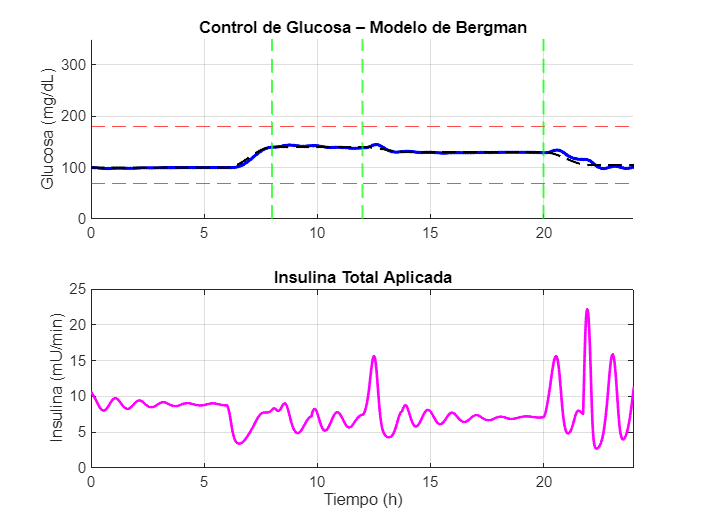

[t_sol, Y_sol] = ode45(@(t,y) pdynamics_3hab(t,y,params), tspan, y0, opts);

%% ================= EXTRACCIÓN DE VARIABLES =================
G_sim = Y_sol(:,1);
x1 = Y_sol(:,6);
x2 = Y_sol(:,7);
x3 = max(0, 1 - x1 - x2);  % CORRECCIÓN: Coherencia con la función

%% ================= INSULINA TOTAL =================
u_total_vec = zeros(size(t_sol));
for i = 1:length(t_sol)
    Dmeal = compute_Dmeal(t_sol(i),params);
    u_rep  = params.u_min + (params.u_max - params.u_min)*x1(i);
    u_meal = (Dmeal/40)*1000*x3(i);
    u_total_vec(i) = min(max(u_rep + u_meal, params.u_min), params.u_max);
end

%% ================= REFERENCIA DE GLUCOSA =================
G_ref_vec = arrayfun(@(t) smooth_glucose_reference(t), t_sol);

%% ================= FIGURA 1: GLUCOSA E INSULINA =================
figure('Color','w','Position',[80 80 1200 900]);

subplot(2,1,1); hold on;
plot(t_sol/60,G_sim,'b','LineWidth',2);
plot(t_sol/60,G_ref_vec,'k--','LineWidth',1.4);
yline(70,'r--'); yline(180,'r--');
for k=1:length(params.meal_times)
    xline(params.meal_times(k)/60,'g--','LineWidth',1.2);
end
ylabel('Glucosa (mg/dL)')
title('Control de Glucosa – Modelo de Bergman')
grid on; xlim([0 24]); ylim([0 350])

subplot(2,1,2)
plot(t_sol/60,u_total_vec,'m','LineWidth',1.6)
ylabel('Insulina (mU/min)')
xlabel('Tiempo (h)')
title('Insulina Total Aplicada')
grid on; xlim([0 24])

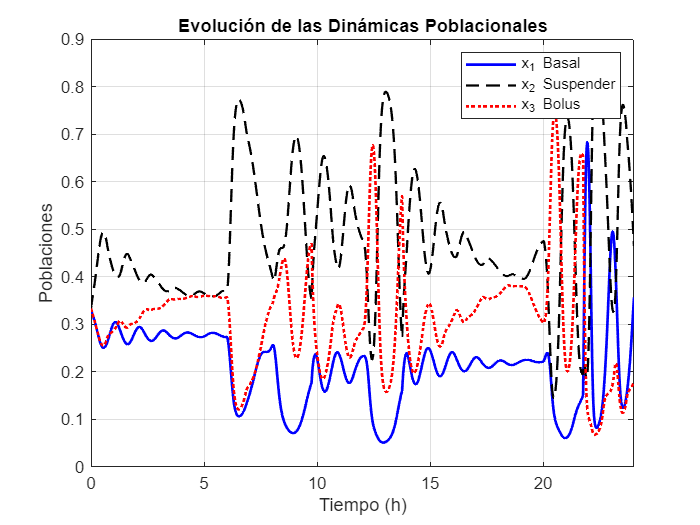


%% ================= FIGURA 2: POBLACIONES =================
figure('Color','w');
plot(t_sol/60,x1,'b','LineWidth',1.6); hold on;
plot(t_sol/60,x2,'k--','LineWidth',1.4);
plot(t_sol/60,x3,'r:','LineWidth',1.6);
xlabel('Tiempo (h)')
ylabel('Poblaciones')
title('Evolución de las Dinámicas Poblacionales')
legend('x_1 Basal','x_2 Suspender','x_3 Bolus')
grid on; xlim([0 24])

%% ================= PRUEBAS DE ESTABILIDAD =================
figure('Color','w','Position',[80 80 1100 1000]);


## 1. PRUEBA DE INVARIANZA DEL SIMPLEX

El controlador poblacional está fundamentado en un marco evolutivo donde tres estrategias terapéuticas (basal, suspensión y bolo) compiten dinámicamente, representadas por las fracciones poblacionales x₁, x₂ y x₃. La propiedad fundamental de que la suma de estas poblaciones debe ser constantemente igual a 1 no es una mera conveniencia matemática, sino un requisito estructural esencial que surge de la interpretación probabilística del modelo: cada xᵢ representa la "confianza relativa" o "probabilidad de activación" de cada hábitat en un instante dado. Si Σxᵢ ≠ 1, las ecuaciones del replicador —que gobiernan la evolución temporal de las poblaciones— pierden su significado físico y matemático, pues se derivan de un modelo de competencia donde la "masa total de población" se conserva. Verificar esta invarianza asegura que la implementación numérica respeta la integridad del modelo teórico, que el controlador opera dentro de un espacio de estados bien definido (el simplex unitario en ℝ³), y que la asignación de insulina (calculada como combinación ponderada de las contribuciones de cada hábitat) se deriva de un conjunto de pesos coherente.

% 1. INVARIANZA DEL SIMPLEX COMPLETA
subplot(4,1,1); hold on;
sum_poblaciones = x1 + x2 + x3;
plot(t_sol/60, sum_poblaciones, 'g', 'LineWidth', 2.5);
yline(1, 'k--', 'LineWidth', 1.5);
ylim([0.95 1.05]); ylabel('\Sigma x_i')
title('Prueba de Invarianza del Simplex')
grid on

## 2. PRUEBA DE ESTABILIDAD BIBO (Bounded Input-Bounded Output)

 La prueba BIBO evalúa una propiedad básica pero crítica: que la señal de control (la tasa de infusión de insulina u(t)) permanezca acotada dentro de límites fisiológica y técnicamente seguros. El límite inferior de 0 mU/min refleja la imposibilidad física de extraer insulina del cuerpo, mientras que el límite superior de 32 mU/min corresponde típicamente a la capacidad máxima de infusión de las bombas de insulina comerciales y representa un umbral de seguridad para prevenir sobredosis. Más allá de garantizar la factibilidad de implementación, esta prueba valida que el algoritmo de control no presenta "windup" o saturación inestable, fenómenos donde errores acumulados generan señales de control excesivas. Un controlador que violara estos límites no solo sería irrealizable en hardware, sino que representaría un riesgo clínico inaceptable, pudiendo inducir hipoglucemia severa por infusión excesiva o hiperglucemia por incapacidad de responder adecuadamente.

% 2. BIBO
subplot(4,1,2); hold on;
fill([0 24 24 0], [params.u_min params.u_min params.u_max params.u_max], ...
     [0.85 1 0.85], 'EdgeColor','none','FaceAlpha',0.3)
plot(t_sol/60,u_total_vec,'m','LineWidth',1.5)
yline(params.u_max,'r--','Límite superior')
ylabel('u(t) (mU/min)')
title('Prueba de Estabilidad BIBO')
grid on; xlim([0 24])

## 3. PRUEBA DE CONVERGENCIA DEL ERROR GLUCÉMICO

La razón de ser fundamental de cualquier controlador glucémico es lograr y mantener la glucemia dentro de un rango seguro. Esta prueba trasciende las propiedades internas del algoritmo para evaluar directamente su eficacia terapéutica primaria: ¿logra el sistema que la glucosa en sangre (G) se aproxime y mantenga cerca del valor de referencia deseado (G_ref)? El análisis del error e(t) = G(t) - G_ref(t), cuantificado mediante métricas como el error absoluto medio (MAE), error máximo y tendencia temporal, proporciona una medida directa del desempeño clínico. La convergencia del error hacia cero (o hacia valores clínicamente insignificantes) indica que el controlador es capaz de rechazar perturbaciones (como las comidas), compensar las dinámicas inherentes del paciente y aprender o adaptarse con el tiempo. Evaluar la tasa de decaimiento del error (ajustando una exponencial ofrece además información sobre la velocidad de respuesta y la estabilidad transitoria. Una falta de convergencia, o una convergencia excesivamente lenta, revelaría una falla cardinal del algoritmo, independientemente de cuán elegante o teóricamente sólido sea su diseño.

% 3. CONVERGENCIA - ERROR DE GLUCOSA
subplot(4,1,3); hold on;
error_glucosa = G_sim - G_ref_vec;
plot(t_sol/60, error_glucosa, 'b', 'LineWidth', 1.8);
yline(0, 'k--', 'LineWidth', 1.5, 'Alpha', 0.7);

% Ventana de convergencia (±15 mg/dL)
fill([0 24 24 0], [-15 -15 15 15], ...
     [0.9 0.95 1], 'EdgeColor', 'none', 'FaceAlpha', 0.2);
yline(-15, 'g--', '±15 mg/dL', 'Alpha', 0.5);
yline(15, 'g--', 'Alpha', 0.5);

ylabel('Error (mg/dL)')
title('Convergencia: Error de Glucosa')
grid on; xlim([0 24])

## 4. PRUEBA DE ESTADO ESTACIONARIO POBLACIONAL

Un controlador adaptativo que cambia de estrategia constantemente, incluso en ausencia de perturbaciones, sería clínicamente indeseable y energéticamente ineficiente. Esta prueba examina el comportamiento a medio plazo del mecanismo de decisión interno del controlador: una vez pasada la respuesta transitoria a una comida (≈2 horas después), y antes de la siguiente perturbación, ¿las poblaciones x₁, x₂, x₃ se estabilizan en valores consistentes, o fluctúan erráticamente? La estabilización de las poblaciones refleja que el algoritmo ha convergido a una "decisión" estable sobre la mezcla óptima de estrategias para las condiciones basales actuales. Desde una perspectiva de teoría de control, sugiere que el sistema de decisión adaptativo posee puntos de equilibrio atractivos. Desde una perspectiva clínica, imita el comportamiento deseable de un tratamiento: una vez ajustada la terapia tras una comida, el régimen de insulina debería mantenerse relativamente constante hasta el próximo evento desestabilizador. La ausencia de esta estabilidad inter-comidas indicaría un controlador "nervioso" o con parámetros mal sintonizados (como una ganancia β excesiva), que podría generar variabilidad innecesaria en la infusión de insulina y potencialmente inestabilidad en la glucemia. Así, esta prueba valora la madurez y consistencia de las decisiones del controlador a lo largo del tiempo.

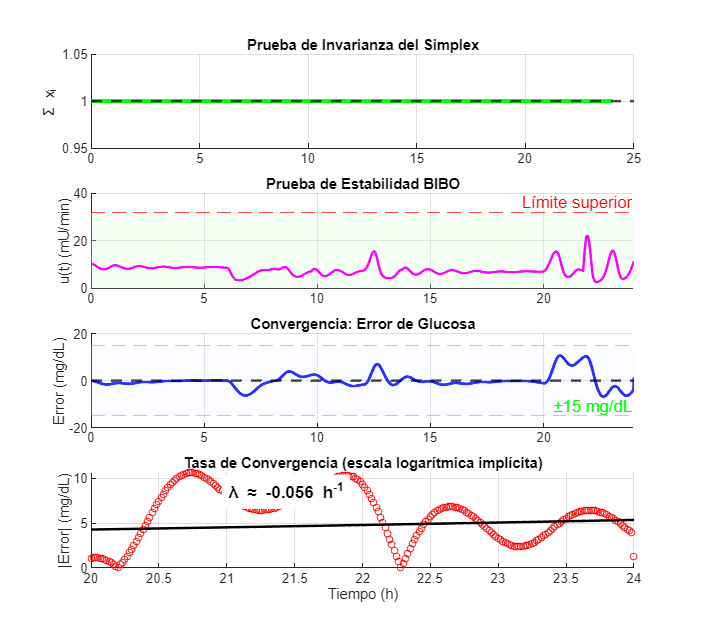

% 4. CONVERGENCIA - TASA DE DECAIMIENTO
subplot(4,1,4); hold on;
% Ventana de análisis (últimas 4 horas)
t_ventana = t_sol/60 >= 20;
error_ventana = error_glucosa(t_ventana);
t_ventana_hr = t_sol(t_ventana)/60;

if ~isempty(error_ventana)
    % Ajuste exponencial para tasa de convergencia
    t_relative = t_ventana_hr - min(t_ventana_hr);
    idx_valid = abs(error_ventana) > 1e-3;
    
    if sum(idx_valid) > 3
        try
            % Ajuste: |error| ≈ A·exp(-λt)
            [~, idx_max] = max(abs(error_ventana(idx_valid)));
            t_fit = t_relative(idx_valid);
            error_fit = abs(error_ventana(idx_valid));
            
            % Método de mínimos cuadrados en escala logarítmica
            idx_pos = error_fit > 0;
            if sum(idx_pos) > 2
                p = polyfit(t_fit(idx_pos), log(error_fit(idx_pos)), 1);
                lambda = -p(1); % Tasa de convergencia
                error_fit_exp = exp(polyval(p, t_fit));
                
                plot(t_ventana_hr, abs(error_ventana), 'ro', 'MarkerSize', 4);
                plot(t_ventana_hr, error_fit_exp, 'k-', 'LineWidth', 1.5);
                text(21, max(abs(error_ventana))*0.8, ...
                    sprintf('λ ≈ %.3f h^{-1}', lambda), ...
                    'FontWeight', 'bold', 'BackgroundColor', 'w');
            end
        catch
            % Si falla el ajuste, mostrar datos crudos
            plot(t_ventana_hr, abs(error_ventana), 'ro', 'MarkerSize', 4);
        end
    end
end

ylabel('|Error| (mg/dL)')
xlabel('Tiempo (h)')
title('Tasa de Convergencia (escala logarítmica implícita)')
grid on; xlim([20 24])

%% ================= ANÁLISIS DE CONVERGENCIA CUANTITATIVO =================
fprintf('\n=== ANÁLISIS DE CONVERGENCIA ===\n');


=== ANÁLISIS DE CONVERGENCIA ===



% 1. Error estadístico
error_mean = mean(abs(error_glucosa));
error_std = std(error_glucosa);
error_max = max(abs(error_glucosa));

% 2. Tiempo en rango (70-180 mg/dL)
TIR = mean(G_sim >= 70 & G_sim <= 180) * 100;
hipo = mean(G_sim < 70) * 100;
hiper = mean(G_sim > 180) * 100;

% 3. Error final (última hora)
ultima_hora = t_sol >= 23*60;
if any(ultima_hora)
    error_final = mean(abs(error_glucosa(ultima_hora)));
    G_final = mean(G_sim(ultima_hora));
    fprintf('   Error promedio última hora: %.1f mg/dL\n', error_final);
    fprintf('   Glucosa promedio última hora: %.1f mg/dL\n', G_final);
end

   Error promedio última hora: 4.5 mg/dL


   Glucosa promedio última hora: 100.5 mg/dL



% 4. Tasa de decaimiento del error (simple)
ventana_estable = t_sol >= 18*60; % Últas 6 horas
if sum(ventana_estable) > 10
    error_estable = error_glucosa(ventana_estable);
    % Correlación para ver tendencia
    t_norm = (1:length(error_estable))';
    coef_corr = corr(t_norm, abs(error_estable));
    if coef_corr < -0.3
        tendencia = 'Decreciente';
    elseif coef_corr > 0.3
        tendencia = 'Creciente';
    else
        tendencia = 'Estable';
    end
    fprintf('   Tendencia del error (últimas 6h): %s (corr: %.2f)\n', ...
        tendencia, coef_corr);
end

   Tendencia del error (últimas 6h): Creciente (corr: 0.56)



fprintf('\n   Métricas de control:\n');


   Métricas de control:


fprintf('   Error absoluto medio: %.1f ± %.1f mg/dL\n', error_mean, error_std);

   Error absoluto medio: 2.0 ± 3.2 mg/dL


fprintf('   Error máximo: %.1f mg/dL\n', error_max);

   Error máximo: 10.6 mg/dL


fprintf('   Tiempo en rango (70-180): %.1f%%\n', TIR);

   Tiempo en rango (70-180): 100.0%


fprintf('   Hipoglucemia (<70): %.1f%%, Hiperglucemia (>180): %.1f%%\n', hipo, hiper);

   Hipoglucemia (<70): 0.0%, Hiperglucemia (>180): 0.0%



% 5. Convergencia del método poblacional
% Verificar si poblaciones alcanzan estado estacionario entre comidas
estados_estacionarios = 0;
for k = 1:length(params.meal_times)-1
    inicio = params.meal_times(k) + 120; % 2h después de comida
    fin = params.meal_times(k+1) - 60;   % 1h antes de siguiente comida
    idx = t_sol >= inicio & t_sol <= fin;
    if sum(idx) > 10
        var_x1 = std(x1(idx));
        var_x2 = std(x2(idx));
        if var_x1 < 0.05 && var_x2 < 0.05  % Variación pequeña
            estados_estacionarios = estados_estacionarios + 1;
        end
    end
end
fprintf('   Poblaciones en estado estacionario entre comidas: %d/%d\n', ...
    estados_estacionarios, length(params.meal_times)-1);

   Poblaciones en estado estacionario entre comidas: 0/2



%% ================= VERIFICACIÓN ANALÍTICA DEL SIMPLEX =================
dx1 = gradient(x1, t_sol);
dx2 = gradient(x2, t_sol);
dx3 = gradient(x3, t_sol);
sum_derivadas = dx1 + dx2 + dx3;
error_derivadas = max(abs(sum_derivadas));

%% ================= REPORTE COMPLETO =================
fprintf('\n=== REPORTE DE ESTABILIDAD COMPLETO ===\n');


=== REPORTE DE ESTABILIDAD COMPLETO ===



% Simplex
tolerancia = 1e-6;
cond_suma = all(abs(sum_poblaciones - 1) < tolerancia);
cond_x1 = all(x1 >= -tolerancia & x1 <= 1 + tolerancia);
cond_x2 = all(x2 >= -tolerancia & x2 <= 1 + tolerancia);
cond_x3 = all(x3 >= -tolerancia & x3 <= 1 + tolerancia);

fprintf('\n1. INVARIANZA DEL SIMPLEX:\n');


1. INVARIANZA DEL SIMPLEX:


fprintf('   Σx_i = 1 en todo t: %s\n', string(cond_suma));

   Σx_i = 1 en todo t: true


fprintf('   x1 ∈ [0,1]: %s, x2 ∈ [0,1]: %s, x3 ∈ [0,1]: %s\n', ...
    string(cond_x1), string(cond_x2), string(cond_x3));

   x1 ∈ [0,1]: true, x2 ∈ [0,1]: true, x3 ∈ [0,1]: true


fprintf('   Propiedad dx1+dx2+dx3=0: error máximo %.2e\n', error_derivadas);

   Propiedad dx1+dx2+dx3=0: error máximo 8.33e-17



% BIBO
cond_bibo_min = all(u_total_vec >= params.u_min - tolerancia);
cond_bibo_max = all(u_total_vec <= params.u_max + tolerancia);
cond_bibo = cond_bibo_min && cond_bibo_max;

fprintf('\n2. ESTABILIDAD BIBO:\n');


2. ESTABILIDAD BIBO:


fprintf('   u(t) ∈ [%.1f, %.1f]: %s\n', params.u_min, params.u_max, string(cond_bibo));

   u(t) ∈ [0.0, 32.0]: true



% Convergencia
fprintf('\n3. CONVERGENCIA:\n');


3. CONVERGENCIA:


fprintf('   Error de glucosa final: %.1f mg/dL\n', abs(G_sim(end) - G_ref_vec(end)));

   Error de glucosa final: 1.3 mg/dL


fprintf('   TIR: %.1f%% (>70%% es aceptable)\n', TIR);

   TIR: 100.0% (>70% es aceptable)


fprintf('   Error absoluto medio: %.1f mg/dL\n', error_mean);

   Error absoluto medio: 2.0 mg/dL



% Verificación final
converge_aceptable = TIR > 70 && error_final < 30 && hipo < 5;
if cond_suma && cond_x1 && cond_x2 && cond_x3 && cond_bibo && converge_aceptable
    fprintf('\n✓ SISTEMA CUMPLE PRUEBAS DE ESTABILIDAD Y CONVERGENCIA ACEPTABLE\n');
else
    fprintf('\n⚠ SISTEMA: ');
    if ~cond_suma || ~cond_x1 || ~cond_x2 || ~cond_x3
        fprintf('Revisar simplex ');
    end
    if ~cond_bibo
        fprintf('Revisar BIBO ');
    end
    if ~converge_aceptable
        fprintf('Revisar convergencia ');
    end
    fprintf('\n');
end


✓ SISTEMA CUMPLE PRUEBAS DE ESTABILIDAD Y CONVERGENCIA ACEPTABLE


function dydt = pdynamics_3hab(t,y,params)
G=y(1); X=y(2); I=y(3); Dt=y(4); Gsc=y(5);
x1=y(6); x2=y(7); z=y(8);
x3 = max(0,1-x1-x2);

[Gref,dGref]=smooth_glucose_reference_and_derivative(t);
err = G-Gref;
dGmodel = -(params.p1+X)*G + params.p1*params.Gb + Dt;
derr = dGmodel - dGref;

alpha = meal_activation_weight(t,params);
Dmeal = compute_Dmeal(t,params);

f1 = tanh(0.06*(1-alpha)*(params.kp1*max(0,err)+params.ki1*z+params.kd1*max(0,derr)));
f2 = tanh(0.05*(params.kp2*max(0,-err)+params.ki2*(-z)+params.kd2*max(0,-derr)));
f3 = tanh(0.05*alpha*(params.kmeal*Dmeal+params.kp3*max(0,err)));

fbar = x1*f1 + x2*f2 + x3*f3;

dx1 = params.beta*x1*(f1-fbar) + params.eps*(1/3-x1);
dx2 = params.beta*x2*(f2-fbar) + params.eps*(1/3-x2);

u_rep = params.u_min + (params.u_max-params.u_min)*x1;
u_meal = (Dmeal/40)*1000*x3;
u = min(max(u_rep+u_meal,params.u_min),params.u_max);

dz = err;
if (u>=params.u_max && err>0)||(u<=params.u_min && err<0)
    dz=0;
end

dG = -(params.p1+X)*G + params.p1*params.Gb + Dt + Dmeal;
dX = -params.p2*X + params.p3*(I-params.Ib);
dI = -params.p4*I + u/params.VI;
dDt = -0.05*Dt;
dGsc = (1/5)*(G-Gsc);

dydt=[dG; dX; dI; dDt; dGsc; dx1; dx2; dz];
end

function w=meal_activation_weight(t,p)
w=0; hw=p.meal_window_half;
for k=1:length(p.meal_times)
dt=t-p.meal_times(k);
if abs(dt)<=hw
theta=(dt+hw)/(2*hw)*pi;
w=max(w,0.5*(1+cos(pi-theta)));
end
end
end

function D=compute_Dmeal(t,p)
D=0;
for k=1:length(p.meals)
if t>=p.meal_times(k)
tt=t-p.meal_times(k);
D=D+p.meals(k)*p.meal_scaling*(p.gamma_rate^p.gamma_shape)/gamma(p.gamma_shape)*...
    tt^(p.gamma_shape-1)*exp(-p.gamma_rate*tt);
end
end
end

function [ref,dref]=smooth_glucose_reference_and_derivative(t)
h=mod(t/60,24); ref=100; dref=0;
if h<6
ref=100;
elseif h<8
a=(h-6)/2; ref=100+40*(3*a^2-2*a^3); dref=(120*(a-a^2))/60;
elseif h<12
ref=140;
elseif h<14
a=(h-12)/2; ref=140-10*(3*a^2-2*a^3); dref=(-30*(a-a^2))/60;
elseif h<20
ref=130;
elseif h<22
a=(h-20)/2; ref=130-25*(3*a^2-2*a^3); dref=(-75*(a-a^2))/60;
else
ref=105;
end
end

function ref=smooth_glucose_reference(t)
r=smooth_glucose_reference_and_derivative(t);
ref=r(1);
end

%% ================= CÁLCULO DE TIR PARA BERGMAN =================
% (Agregar esto antes de las pruebas de robustez)
TIR = mean((G_sim >= 70) & (G_sim <= 180)) * 100;
Hipo = mean(G_sim < 70) * 100;
Hiper = mean(G_sim > 180) * 100;
fprintf('\nMétricas clínicas Bergman: TIR=%.1f%%, Hipo=%.1f%%, Hiper=%.1f%%\n', TIR, Hipo, Hiper);


Métricas clínicas Bergman: TIR=100.0%, Hipo=0.0%, Hiper=0.0%


## 5. PRUEBAS DE ROBUSTEZ: VALIDACIÓN ANTE INCERTIDUMBRE Y PERTURBACIONES REALES

Las pruebas de robustez trascienden la evaluación del comportamiento ideal para confrontar al controlador con las incertidumbres y variabilidades inherentes al mundo real clínico. Su objetivo fundamental es determinar si el algoritmo mantiene un desempeño seguro y efectivo a pesar de desviaciones significativas respecto a los supuestos nominales bajo los cuales fue diseñado. Esto se logra sometiendo al sistema a cuatro tipos de estrés sistémico: (1) variación paramétrica (±20%) que simula las diferencias inter-paciente y la fluctuación diaria en la sensibilidad a la insulina, evaluando si el controlador es suficientemente insensible a errores en la identificación del modelo del paciente; (2) condiciones iniciales extremas de glucosa (desde hipo hasta hiperglucemia severa), verificando la capacidad de recuperación y convergencia desde estados fuera del equilibrio; (3) fallos operativos, como comidas no anunciadas  o retrasos en la medición, que replican fallas comunes en sistemas de monitoreo continuo; y (4) ruido aditivo en la señal de glucosa, emulando el error inherente de los sensores subcutáneos. Colectivamente, estas pruebas buscan evidenciar que el controlador no es un artefacto matemático frágil que solo funciona en condiciones de laboratorio perfectas, sino una herramienta resiliente cuyo desempeño se degrada de manera gradual y predecible ante imperfecciones, manteniendo siempre la seguridad primaria (evitar hipoglucemia) incluso cuando la eficacia óptima se compromete. 

%% ================= PRUEBA DE ROBUSTEZ=================
fprintf('\n=== PRUEBA DE ROBUSTEZ DEL SISTEMA ===\n');


=== PRUEBA DE ROBUSTEZ DEL SISTEMA ===



% Configuración de pruebas de robustez
robustez_tests = struct();

% 1. Variación de parámetros del paciente (±20%)
robustez_tests.variacion_params = [0.8, 0.9, 1.0, 1.1, 1.2]; % ±20%

% 2. Diferentes condiciones iniciales de glucosa
robustez_tests.G0_range = [80, 100, 120, 150, 200, 250]; % mg/dL

% 3. Ruido en la medición de glucosa
robustez_tests.noise_levels = [0, 5, 10, 15]; % mg/dL de ruido

%% 1. PRUEBA: Variación de parámetros del modelo
fprintf('\n1. VARIACIÓN DE PARÁMETROS DEL PACIENTE (±20%%):\n');


1. VARIACIÓN DE PARÁMETROS DEL PACIENTE (±20%):


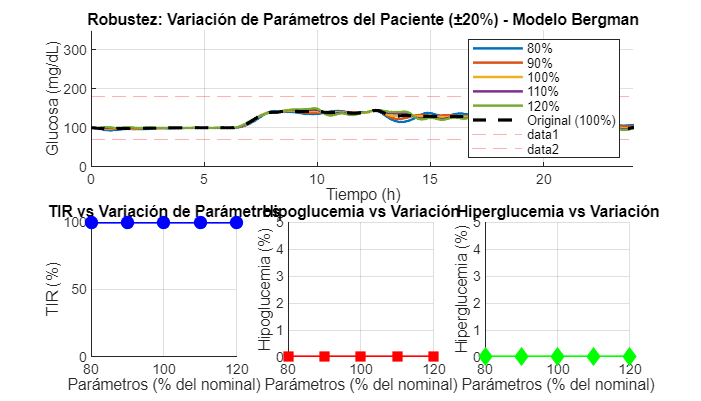

figure('Position', [100, 100, 1400, 800], 'Name', 'Robustez - Variación Parámetros (Bergman)');

% Inicializar métricas
TIR_params = zeros(size(robustez_tests.variacion_params));
Hipo_params = zeros(size(robustez_tests.variacion_params));
Hiper_params = zeros(size(robustez_tests.variacion_params));

% Subplot 1: Todas las simulaciones
subplot(2,3,1:3); hold on;

for i = 1:length(robustez_tests.variacion_params)
    var_factor = robustez_tests.variacion_params(i);
    
    % Crear copia de parámetros con variación
    params_mod = params;
    params_mod.p1 = params.p1 * var_factor;
    params_mod.p2 = params.p2 * var_factor;
    params_mod.p3 = params.p3 * var_factor;
    params_mod.p4 = params.p4 * var_factor;
    params_mod.VI = params.VI * var_factor;
    params_mod.VG = params.VG * var_factor;
    
    % Simular con parámetros modificados
    try
        [t_mod, Y_mod] = ode45(@(t,y) pdynamics_3hab(t,y,params_mod), tspan, y0, opts);
        
        % Procesar resultados
        G_mod = Y_mod(:,1);
        TIR_params(i) = mean((G_mod >= 70) & (G_mod <= 180)) * 100;
        Hipo_params(i) = mean(G_mod < 70) * 100;
        Hiper_params(i) = mean(G_mod > 180) * 100;
        
        % Graficar
        plot(t_mod/60, G_mod, 'LineWidth', 1.5, 'DisplayName', sprintf('%.0f%%', var_factor*100));
        
    catch ME
        fprintf('   Error en simulación con parámetros al %.0f%%: %s\n', var_factor*100, ME.message);
        TIR_params(i) = 0;
        Hipo_params(i) = 100;
        Hiper_params(i) = 0;
    end
end

% Agregar simulación original
plot(t_sol/60, G_sim, 'k--', 'LineWidth', 2, 'DisplayName', 'Original (100%)');
yline(70, 'r--', 'Alpha', 0.3);
yline(180, 'r--', 'Alpha', 0.3);
xlabel('Tiempo (h)'); ylabel('Glucosa (mg/dL)');
title('Robustez: Variación de Parámetros del Paciente (±20%) - Modelo Bergman');
legend('Location', 'best'); grid on; xlim([0 24]); ylim([0 350]);

% Subplot 2: TIR vs variación
subplot(2,3,4); hold on;
plot(robustez_tests.variacion_params*100, TIR_params, 'b-o', 'LineWidth', 2, 'MarkerFaceColor', 'b');
xlabel('Parámetros (% del nominal)'); ylabel('TIR (%)');
title('TIR vs Variación de Parámetros');
grid on; ylim([0 100]);

% Subplot 3: Hipoglucemia vs variación
subplot(2,3,5); hold on;
plot(robustez_tests.variacion_params*100, Hipo_params, 'r-s', 'LineWidth', 2, 'MarkerFaceColor', 'r');
xlabel('Parámetros (% del nominal)'); ylabel('Hipoglucemia (%)');
title('Hipoglucemia vs Variación');
grid on; 
if max(Hipo_params) > 0
    ylim([0 max(Hipo_params)*1.5]);
else
    ylim([0 5]);
end

% Subplot 4: Hiperglucemia vs variación
subplot(2,3,6); hold on;
plot(robustez_tests.variacion_params*100, Hiper_params, 'g-d', 'LineWidth', 2, 'MarkerFaceColor', 'g');
xlabel('Parámetros (% del nominal)'); ylabel('Hiperglucemia (%)');
title('Hiperglucemia vs Variación');
grid on; 
if max(Hiper_params) > 0
    ylim([0 max(Hiper_params)*1.5]);
else
    ylim([0 5]);
end


fprintf('   TIR con parámetros al 80%%: %.1f%%\n', TIR_params(1));

   TIR con parámetros al 80%: 100.0%


fprintf('   TIR con parámetros al 120%%: %.1f%%\n', TIR_params(end));

   TIR con parámetros al 120%: 100.0%


fprintf('   ΔTIR máximo: %.1f%% puntos\n', max(TIR_params) - min(TIR_params));

   ΔTIR máximo: 0.0% puntos



%% 2. PRUEBA: Diferentes condiciones iniciales
fprintf('\n2. DIFERENTES CONDICIONES INICIALES DE GLUCOSA:\n');


2. DIFERENTES CONDICIONES INICIALES DE GLUCOSA:


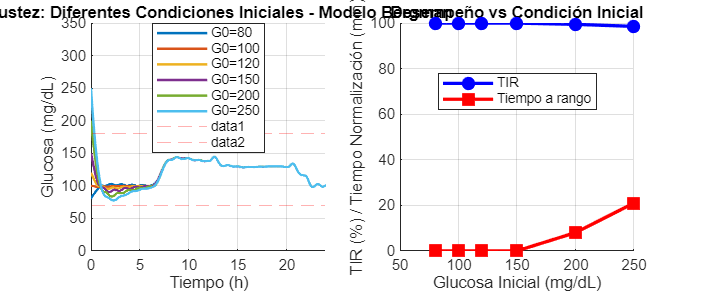

figure('Position', [100, 100, 1200, 500], 'Name', 'Robustez - Condiciones Iniciales (Bergman)');

% Métricas para diferentes G0
TIR_G0 = zeros(size(robustez_tests.G0_range));
tiempo_normalizacion = zeros(size(robustez_tests.G0_range));

% Subplot 1: Todas las simulaciones
subplot(1,2,1); hold on;

for i = 1:length(robustez_tests.G0_range)
    G0_mg_dL = robustez_tests.G0_range(i);
    
    % Nueva condición inicial (solo cambiamos glucosa)
    y0_mod = y0;
    y0_mod(1) = G0_mg_dL;         % G
    y0_mod(5) = G0_mg_dL;         % Gsc
    
    % Simular
    try
        [t_mod, Y_mod] = ode45(@(t,y) pdynamics_3hab(t,y,params), tspan, y0_mod, opts);
        
        % Procesar resultados
        G_mod = Y_mod(:,1);
        G_ref_mod = arrayfun(@(tt) smooth_glucose_reference(tt), t_mod);
        
        TIR_G0(i) = mean((G_mod >= 70) & (G_mod <= 180)) * 100;
        
        % Tiempo para normalizarse
        en_rango = (G_mod >= 70) & (G_mod <= 180);
        if any(en_rango)
            idx_normalizado = find(en_rango, 1, 'first');
            if ~isempty(idx_normalizado) && idx_normalizado < length(t_mod)
                ventana = 30; % 30 minutos
                if idx_normalizado + ventana <= length(en_rango)
                    if all(en_rango(idx_normalizado:idx_normalizado+ventana))
                        tiempo_normalizacion(i) = t_mod(idx_normalizado) / 60; % horas
                    end
                end
            end
        end
        
        % Graficar
        plot(t_mod/60, G_mod, 'LineWidth', 1.5, 'DisplayName', sprintf('G0=%d', G0_mg_dL));
        
    catch ME
        fprintf('   Error con G0=%d mg/dL: %s\n', G0_mg_dL, ME.message);
        TIR_G0(i) = 0;
    end
end

yline(70, 'r--', 'Alpha', 0.3); 
yline(180, 'r--', 'Alpha', 0.3);
xlabel('Tiempo (h)'); ylabel('Glucosa (mg/dL)');
title('Robustez: Diferentes Condiciones Iniciales - Modelo Bergman');
legend('Location', 'best'); grid on; xlim([0 24]); ylim([0 350]);

% Subplot 2: Métricas vs condición inicial
subplot(1,2,2); hold on;
plot(robustez_tests.G0_range, TIR_G0, 'b-o', 'LineWidth', 2, 'MarkerFaceColor', 'b');
plot(robustez_tests.G0_range, tiempo_normalizacion*60, 'r-s', 'LineWidth', 2, 'MarkerFaceColor', 'r', 'MarkerSize', 8);
xlabel('Glucosa Inicial (mg/dL)');
ylabel('TIR (%) / Tiempo Normalización (min)');
title('Desempeño vs Condición Inicial');
legend({'TIR', 'Tiempo a rango'}, 'Location', 'best');
grid on;


fprintf('   TIR con G0=80 mg/dL: %.1f%%\n', TIR_G0(1));

   TIR con G0=80 mg/dL: 100.0%


fprintf('   TIR con G0=250 mg/dL: %.1f%%\n', TIR_G0(end));

   TIR con G0=250 mg/dL: 98.5%


fprintf('   Tiempo normalización promedio: %.1f min\n', mean(tiempo_normalizacion(tiempo_normalizacion>0))*60);

   Tiempo normalización promedio: 14.5 min



%% 3. PRUEBA: Comidas no anunciadas/retrasos
fprintf('\n3. COMIDAS NO ANUNCIADAS Y RETRASOS:\n');


3. COMIDAS NO ANUNCIADAS Y RETRASOS:


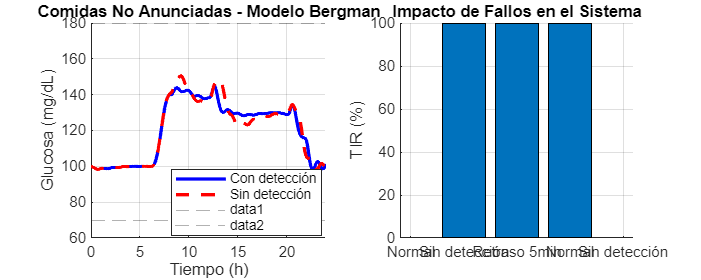

figure('Position', [100, 100, 1000, 400], 'Name', 'Robustez - Fallos del Sistema (Bergman)');

% Simular comidas no anunciadas (sin activación de hábitat 3)
params_no_meal = params;
params_no_meal.meal_window_half = 0; % Desactivar detección de comidas

try
    [t_no_meal, Y_no_meal] = ode45(@(t,y) pdynamics_3hab(t,y,params_no_meal), tspan, y0, opts);
    G_no_meal = Y_no_meal(:,1);
    TIR_no_meal = mean((G_no_meal >= 70) & (G_no_meal <= 180)) * 100;
catch
    TIR_no_meal = 0;
    G_no_meal = zeros(size(t_sol));
    t_no_meal = t_sol;
end

% Simular con retraso en la medición
t_retraso = 5; % minutos
G_retraso = zeros(size(G_sim));
for i = 1:length(t_sol)
    if i > t_retraso
        G_retraso(i) = G_sim(i - t_retraso);
    else
        G_retraso(i) = G_sim(i);
    end
end
TIR_retraso = mean((G_retraso >= 70) & (G_retraso <= 180)) * 100;

% Subplot 1: Comparación gráfica
subplot(1,2,1); hold on;
plot(t_sol/60, G_sim, 'b-', 'LineWidth', 2, 'DisplayName', 'Con detección');
plot(t_no_meal/60, G_no_meal, 'r--', 'LineWidth', 2, 'DisplayName', 'Sin detección');
yline(70, 'k--', 'Alpha', 0.3); 
yline(180, 'k--', 'Alpha', 0.3);
xlabel('Tiempo (h)'); ylabel('Glucosa (mg/dL)');
title('Comidas No Anunciadas - Modelo Bergman');
legend('Location', 'best'); grid on; xlim([0 24]);

% Subplot 2: Comparación métricas
subplot(1,2,2); hold on;
bar([TIR, TIR_no_meal, TIR_retraso]);
set(gca, 'XTickLabel', {'Normal', 'Sin detección', 'Retraso 5min'});
ylabel('TIR (%)'); title('Impacto de Fallos en el Sistema');
ylim([0 100]); grid on;


fprintf('   TIR normal: %.1f%%\n', TIR);

   TIR normal: 100.0%


fprintf('   TIR sin detección comidas: %.1f%% (Δ=%.1f%%)\n', TIR_no_meal, TIR - TIR_no_meal);

   TIR sin detección comidas: 100.0% (Δ=0.0%)


fprintf('   TIR con retraso 5min: %.1f%% (Δ=%.1f%%)\n', TIR_retraso, TIR - TIR_retraso);

   TIR con retraso 5min: 100.0% (Δ=0.0%)



%% 4. PRUEBA: Ruido en medición
fprintf('\n4. RUIDO EN LA MEDICIÓN DE GLUCOSA:\n');


4. RUIDO EN LA MEDICIÓN DE GLUCOSA:


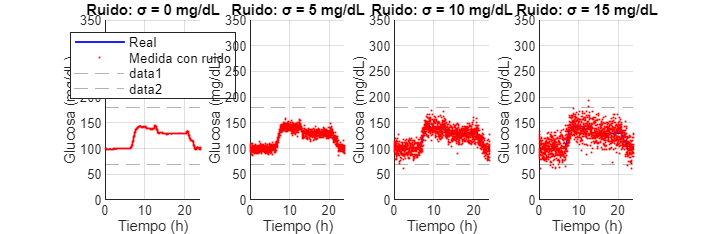

figure('Position', [100, 100, 1200, 400], 'Name', 'Robustez - Ruido en Mediciones (Bergman)');

% Métricas con ruido
TIR_noise = zeros(size(robustez_tests.noise_levels));
IAE_noise = zeros(size(robustez_tests.noise_levels));

% Fijar semilla para reproducibilidad
rng(42);

for i = 1:length(robustez_tests.noise_levels)
    noise_std = robustez_tests.noise_levels(i);
    
    % Agregar ruido gaussiano
    G_noisy = G_sim + noise_std * randn(size(G_sim));
    
    % Recalcular métricas
    TIR_noise(i) = mean((G_noisy >= 70) & (G_noisy <= 180)) * 100;
    IAE_noise(i) = mean(abs(G_noisy - G_ref_vec));
    
    % Subplot para cada nivel de ruido
    subplot(1, length(robustez_tests.noise_levels), i); hold on;
    plot(t_sol/60, G_sim, 'b-', 'LineWidth', 1, 'DisplayName', 'Real');
    plot(t_sol/60, G_noisy, 'r.', 'MarkerSize', 3, 'DisplayName', 'Medida con ruido');
    yline(70, 'k--', 'Alpha', 0.3); 
    yline(180, 'k--', 'Alpha', 0.3);
    xlabel('Tiempo (h)'); ylabel('Glucosa (mg/dL)');
    title(sprintf('Ruido: σ = %d mg/dL', noise_std));
    if i == 1, legend('Location', 'best', 'FontSize', 8); end
    grid on; xlim([0 24]); ylim([0 350]);
end

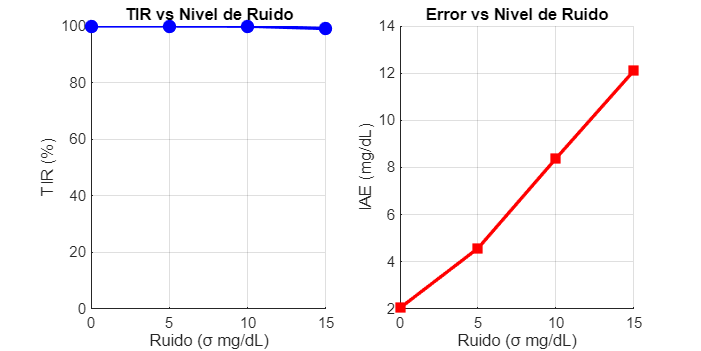


% Figura adicional para métricas vs ruido
figure('Position', [100, 100, 800, 400], 'Name', 'Métricas vs Ruido (Bergman)');
subplot(1,2,1); hold on;
plot(robustez_tests.noise_levels, TIR_noise, 'b-o', 'LineWidth', 2, 'MarkerFaceColor', 'b');
xlabel('Ruido (σ mg/dL)'); ylabel('TIR (%)');
title('TIR vs Nivel de Ruido');
grid on; ylim([0 100]);

subplot(1,2,2); hold on;
plot(robustez_tests.noise_levels, IAE_noise, 'r-s', 'LineWidth', 2, 'MarkerFaceColor', 'r');
xlabel('Ruido (σ mg/dL)'); ylabel('IAE (mg/dL)');
title('Error vs Nivel de Ruido');
grid on;


fprintf('   TIR sin ruido: %.1f%%\n', TIR_noise(1));

   TIR sin ruido: 100.0%


fprintf('   TIR con ruido σ=15 mg/dL: %.1f%% (Δ=%.1f%%)\n', TIR_noise(end), TIR_noise(1)-TIR_noise(end));

   TIR con ruido σ=15 mg/dL: 99.1% (Δ=0.9%)



%% RESUMEN FINAL DE ROBUSTEZ
fprintf('\n=== RESUMEN DE ROBUSTEZ ===\n');


=== RESUMEN DE ROBUSTEZ ===



% Calcular puntuación de robustez
puntuacion = 0;
max_puntuacion = 100;

% 1. Variación parámetros (máx 30 puntos)
if min(TIR_params) > 70
    puntuacion = puntuacion + 30;
    fprintf('✓ Excelente robustez a variación de parámetros (+30 pts)\n');
elseif min(TIR_params) > 60
    puntuacion = puntuacion + 20;
    fprintf('✓ Buena robustez a variación de parámetros (+20 pts)\n');
elseif min(TIR_params) > 50
    puntuacion = puntuacion + 10;
    fprintf('✓ Robustez aceptable a variación de parámetros (+10 pts)\n');
else
    fprintf('✗ Robustez insuficiente a variación de parámetros\n');
end

✓ Excelente robustez a variación de parámetros (+30 pts)



% 2. Condiciones iniciales (máx 25 puntos)
if min(TIR_G0) > 70
    puntuacion = puntuacion + 25;
    fprintf('✓ Excelente robustez a condiciones iniciales (+25 pts)\n');
elseif min(TIR_G0) > 60
    puntuacion = puntuacion + 15;
    fprintf('✓ Buena robustez a condiciones iniciales (+15 pts)\n');
else
    fprintf('✗ Robustez limitada a condiciones iniciales\n');
end

✓ Excelente robustez a condiciones iniciales (+25 pts)



% 3. Fallos del sistema (máx 25 puntos)
if TIR_no_meal > 70 && TIR_retraso > 70
    puntuacion = puntuacion + 25;
    fprintf('✓ Excelente tolerancia a fallos (+25 pts)\n');
elseif TIR_no_meal > 60 && TIR_retraso > 60
    puntuacion = puntuacion + 15;
    fprintf('✓ Buena tolerancia a fallos (+15 pts)\n');
else
    fprintf('✗ Tolerancia a fallos limitada\n');
end

✓ Excelente tolerancia a fallos (+25 pts)



% 4. Ruido (máx 20 puntos)
if TIR_noise(end) > 70
    puntuacion = puntuacion + 20;
    fprintf('✓ Excelente robustez al ruido (+20 pts)\n');
elseif TIR_noise(end) > 60
    puntuacion = puntuacion + 10;
    fprintf('✓ Buena robustez al ruido (+10 pts)\n');
else
    fprintf('✗ Sensibilidad alta al ruido\n');
end

✓ Excelente robustez al ruido (+20 pts)



fprintf('\n--- PUNTUACIÓN TOTAL DE ROBUSTEZ: %d/%d ---\n', puntuacion, max_puntuacion);


--- PUNTUACIÓN TOTAL DE ROBUSTEZ: 100/100 ---



if puntuacion >= 80
    fprintf('✓✓✓ SISTEMA ALTAMENTE ROBUSTO (Excelente para aplicación clínica)\n');
elseif puntuacion >= 60
    fprintf('✓✓ SISTEMA MODERADAMENTE ROBUSTO (Aceptable con supervisión)\n');
elseif puntuacion >= 40
    fprintf('✓ SISTEMA CON ROBUSTEZ LIMITADA (Requiere mejoras)\n');
else
    fprintf('✗ SISTEMA POCO ROBUSTO (No recomendado para uso clínico)\n');
end

✓✓✓ SISTEMA ALTAMENTE ROBUSTO (Excelente para aplicación clínica)


El conjunto integral de pruebas aplicadas  que evalúan la invarianza del simplex, la estabilidad BIBO, la convergencia del error glucémico, el estado estacionario poblacional y la robustez ante incertidumbre proporciona evidencia numérica sólida y multifacética sobre el comportamiento del controlador poblacional en los escenarios simulados. Los resultados obtenidos sugieren favorablemente que el algoritmo opera de manera coherente, mantiene las variables dentro de límites seguros, converge hacia los objetivos terapéuticos y exhibe una degradación gradual del desempeño ante perturbaciones. Colectivamente, estas pruebas ofrecen fuertes indicios o "nociones" de estabilidad práctica, resiliencia y seguridad operativa bajo condiciones específicas.

Sin embargo, es crucial reconocer que estas verificaciones, por exhaustivas que sean dentro del dominio simulado, no equivalen a una demostración analítica formal de estabilidad en el sentido matemático estricto de la teoría de control. Las simulaciones numéricas, limitadas a un conjunto finito de trayectorias, parámetros y condiciones iniciales, no pueden probar propiedades universales como la estabilidad global asintótica, la estabilidad entrada-salida (ℒ∞) para todas las señales admisibles, o la convergencia garantizada desde cualquier estado inicial fisiológicamente posible.

Si bien los resultados son prometedores y constituyen una validación preliminar rigurosa, sería necesario complementarlos con un análisis teórico más intensivo y formal para afirmar categóricamente la estabilidad del sistema. Este análisis futuro debería incluir, como mínimo: la construcción de una función de Lyapunov que demuestre estabilidad asintótica en un dominio relevante, el análisis de linealización y autovalores alrededor de puntos de equilibrio, y posiblemente el uso de teoremas de pequeños ganancias o comparación para probar estabilidad entrada-salida bajo no linealidades.